# Práctica: Cinemática de un robot 2R

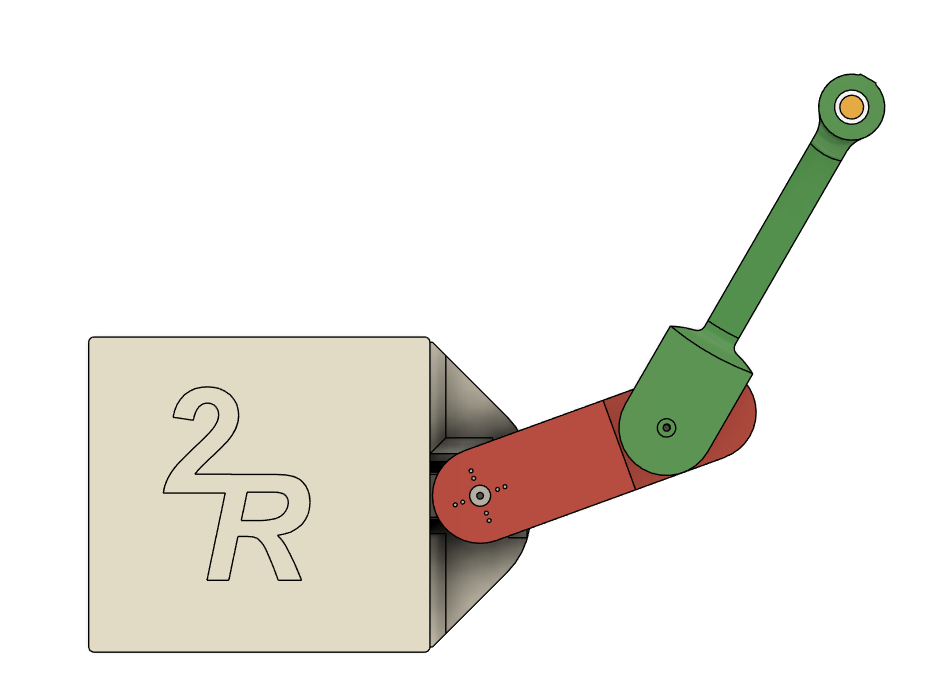

## Cinemática directa

En esta práctica se deben desarrollar las funciones  que resuelven la  cinemática directa del robot 2R

- [x,y] = cinematica_DH(Q1, Q2)

- [x,y] = cinematica_directa_analitica(Q1, Q2)

Estas funcioines se encuentran declaradas dentro del archivo con su mismo nombre. Complétalas para obtener  los resultados esperados.

Para comprobar el correcto funconamiento de las funciones, probar con los siguientes valorers de $q_1$ y $q_2$.


$$q_1 =30º;{\;q}_2 =-50º\longrightarrow x=19\ldotp 6509;y=-1\ldotp 0383$$
   


$$q_1 =-70º;\;q_2 =30º\;\longrightarrow x=13\ldotp 2898;y=-16\ldotp 0467$$
   


$$q_1 =10º;q_2 =-80º\longrightarrow x=12\ldotp 1743;y=-11\ldotp 8533$$
   

q1 = 0
q2 = 0
[x_c, y_c] = cinem_directa_analitica(q1, q2)
[x_dh, y_dh] = cinematica_DH(q1, q2)
 

### Visualización de pose

Con las funciones de la cinemática directa resueltas, podemos visualizar la posición final del efector del robot, conocidas las variables articulares.

Moviendo los *sliders *podemos ver dónde se situaría el efector final del robot para dichas variables articulares.

q1 = 0;
q2 = 0;
[x, y] = cinem_directa_analitica(q1, q2);
figure(1)
plot(x, y, 'r.', 'MarkerSize', 20, "Marker","+")
        hold on
        grid on
        xlim([-15, 23]);
        ylim([-23, 23]);
        xlabel('Eje X'); ylabel('Eje Y');
        title('Posición estimada del robot');
        hold off

### Espacio de trabajo

Conocida la cinemática directa y los rangos de movimiento de cada articulación, también  se puede graficar el espacio de trabajo. Para ello, desarrolla la siguiente función.

- EspacioDeTrabajo()

Abriendo el archivo con este mismo nombre, encontrarás la función declarada. Complétala para conseguir graficar el espacio de trabajo.

EspacioDeTrabajo();
 

## Cinemática inversa

Al igual que se han desarrollado funciones encargadas de resolver la cinemática directa del robot, es necesario desarrollar la cinemática inversa. Esto nos va a permitir crear y planificar trayectorias en  el espacio cartesiano para enviar a nuestro manipulador. En este caso únicamente hay que desarrollar la función:

- [q1, q2] = ik_geometrica(x, y, sigma)

Estas funcioines se encuentran declaradas dentro del archivo con su mismo nombre. Complétalas para obtener  los resultados esperados.

Para comprobar el correcto funconamiento de las funciones, probar con los siguientes valorers de $x$ e $y$.


$$x=19\ldotp 6509;y=-1\ldotp 0383\longrightarrow q_1 =30º;{\;q}_2 =-50º$$
   


$$x=13\ldotp 2898;y=-16\ldotp 0467\longrightarrow \;q_1 =-70º;\;q_2 =30º\;$$
   


$$x=12\ldotp 1743;y=-11\ldotp 8533\longrightarrow q_1 =10º;q_2 =-80º$$
   

Puedes probar con otras coordenadas, para **asegurarte de que pertenecen  al espacio de trabajo**, puedes ayudarte del gráfico que has creado anteriormente.

X = -5.05                        
Y = -17.48
[q1, q2] = ik_geometrica(X, Y, -1)
 

## Trayectorias en articulares

Permite mover el manipulador de un punto a otro sin fijar un recorrido específico. El recorrido para cada articulación será una recta en el espacio de las articulaciones.

Es necesario completar la función encargada de obtener la trayectoria que se puede enviar al manipualdor:

- TrayectoriaArticular(xi, yi, xf, yf);

Para comprobar el correcto funcionamiento de la función,  probar con:


$$x_i =15\ldotp 7;y_i =13\ldotp 5\longrightarrow x_f =17\ldotp 3;y_f =-12\ldotp 5$$
   

sigma = -1;
qMatrix = TrayectoriaArticular(14.11, -15.00, -2.77, -17.98, sigma);
 

## Trayectorias cartesianas

Permite mover el manipulador de un punto a otro **fijando** unrecorrido específico. En este caso, solo se realizarán movimientos en  linea recta. El recorrido para cada articulación no tiene porqué ser una recta en el espacio de las articulaciones.

- TrayectoriaCartesiana(xi, yi, xf, yf, sigma);

Para comprobar el correcto funcionamiento de la función,  probar con:


$$x_i =15\ldotp 7;y_i =13\ldotp 5\longrightarrow x_f =17\ldotp 3;y_f =-12\ldotp 5$$
   

sigma = -1;
qMatrix = TrayectoriaCartesiana(-2.77, -17.98, 14.11, -15.00, sigma);
 

## Conexión con el Robot.

Se busca en las conexiones USB y se espera el comando.

Robot = ArduinoManager();
 

### Enviar comando de posición.

Se envían al robot la posición de q1 y q2. El úlitmo valor asignado, comprobar en el workspace que sea el correcto.

Robot.setServos(q1, q2);
 

### Enviar trayectoria

Se envía la trayectoria al robot. La última qMatrix generada por el código. Comprobar el valor de esta en el workspace.

segundos = 2;
Robot.ejecutarTrayectoria(qMatrix, segundos)
 